load parameters (e.g. the length of each linkage)

load parameters.mat;

以下開始計算機構各支點的座標

thetar= deg2rad(thetad); %convert theta to radian
O_4.x = zeros(1,size(thetad,2)); O_4.y=zeros(1,size(thetad,2));%set O_4 as origin by making it a zero vector of the size of thetad
O3.x =-LO3O_3*cos(thetar); O3.y =LO_3O_4 + LO3O_3*sin(thetar);
O_3.x =zeros(1, size(thetad,2)); O_3.y=LO_3O_4+zeros(1,size(thetad,2));
O4.x= -LO4O_4*cos(thetar); O4.y=LO4O_4*sin(thetar);
O1.x= O3.x; O1.y= O3.y+ LO1O3;
O2.x= O1.x; O2.y=O1.y+LO1O2;
O_1.x= O1.x+LO1O_1*cos(thetar); O_1.y= O1.y+LO1O_1*sin(thetar);
O_2.x= O_1.x; O_2.y= O_1.y+LO1O2;

求各質心座標


$$O_1 O_1^{\prime } :$$


mO1O_1.x = O1.x + RO1O_1 * cos(deg2rad(alphaO1O_1d) + thetar);
mO1O_1.y = O1.y + RO1O_1 * sin(deg2rad(alphaO1O_1d) + thetar);

$O_2 O_2^{\prime }$:

mO2O_2.x = O2.x + RO2O_2 * cos(deg2rad(alphaO2O_2d) + thetar);
mO2O_2.y = O2.y + RO2O_2 * sin(deg2rad(alphaO2O_2d) + thetar);


$O_3 O_3^{\prime }$:

mO3O_3.x = O_3.x - RO3O_3 * cos(deg2rad(alphaO3O_3d) + thetar);
mO3O_3.y = O_3.y + RO3O_3 * sin(deg2rad(alphaO3O_3d) + thetar);

$O_4 O_4^{\prime }$:

mO4O_4.x = O_4.x - RO4O_4 * cos(deg2rad(alphaO4O_4d) + thetar);
mO4O_4.y = O_4.y + RO4O_4 * sin(deg2rad(alphaO4O_4d) + thetar);

$O_1^{\prime } O_2^{\prime }$:

mO_1O_2.x = O_2.x + RO_1O_2 * sin(deg2rad(alphaO_1O_2d));
mO_1O_2.y = O_2.y - RO_1O_2 * cos(deg2rad(alphaO_1O_2d));

$O_2 O_4$:

mO2O4.x = O2.x - RO2O4 * sin(deg2rad(alphaO2O4d));
mO2O4.y = O2.y - RO2O4 * cos(deg2rad(alphaO2O4d));

與彈力材料有關的計算

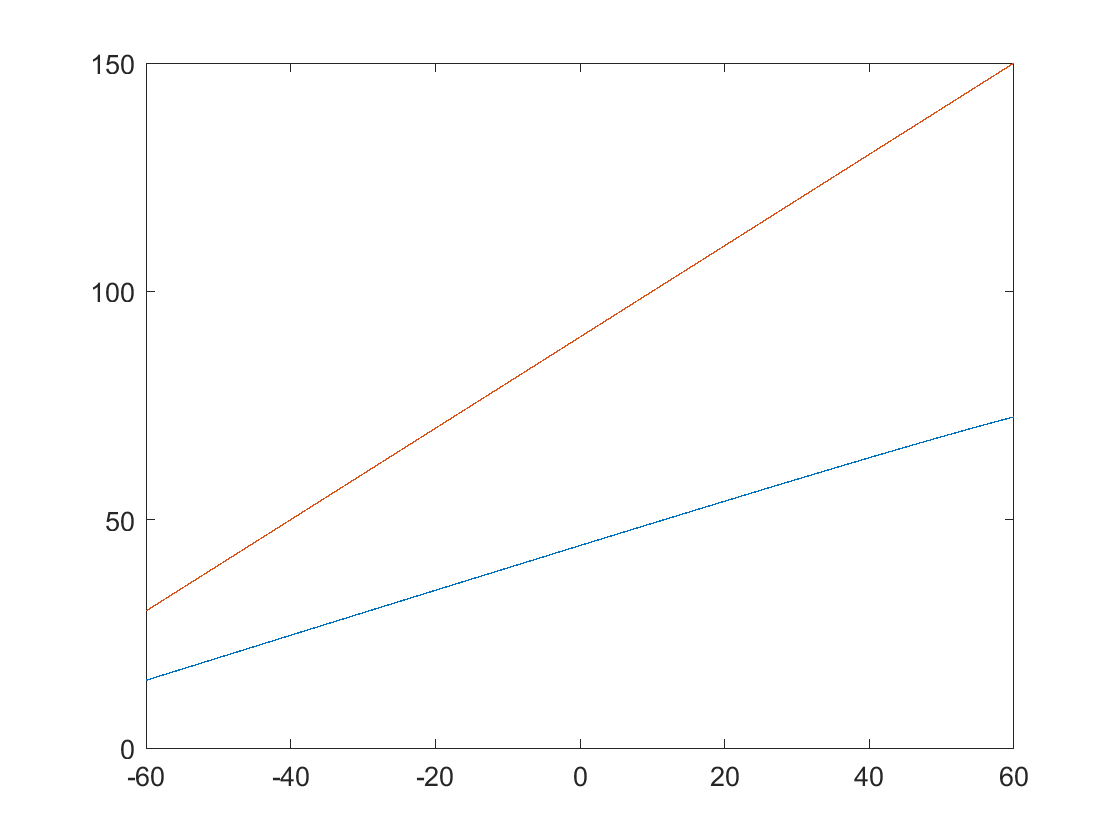

%******橡皮筋相關參量***********%
%*********上部**********%
%i 為該彈性材料在組內的編號
%ki為彈性材料拉力係數 單位為N/mm
%li為彈性材料原長 單位為mm
%Di 為上下桿安裝點距離，即O1P1-O2P2
%調節三Di不同組合
ki=[3.6527  0.3 0.3];
li=[120 120 120];
Di= [260 
     0];
 
%******橡皮筋相關參量***********%
%********下部********%cl
%j 為該彈性材料在組內的編號
%kj為彈性材料拉力係數 單位為N/mm
%lj為彈性材料原長 單位為mm
%Dj 為上下桿安裝點距離，即O1P1-O2P2
%調節三Di不同組合
kj=[0.3 2 2];
lj=[120 120 120];
Dj= [];

%********上部********%
P1i=[]; 
P2i=[];
phii=[];
phiid=[];

for i = 1:length(Di)
    %if else將不同方向的彈性材料分別固定在O1和O_1
    if(Di(i)>=0)
        P1i(i).x=O_1.x; P1i(i).y=O_1.y; %將P1固定在O_1
        P2i(i).x=O2.x+(LO2O_2-Di(i))*cos(thetar); P2i(i).y=O2.y+(LO2O_2-Di(i))*sin(thetar);
    else
        P1i(i).x=O1.x; P1i(i).y=O1.y; %將P1固定在O_1
        P2i(i).x=O2.x+(-Di(i))*cos(thetar); P2i(i).y=O2.y+(-Di(i))*sin(thetar);
    end 
    VP2P1=[P1i(i).x-P2i(i).x; P1i(i).y-P2i(i).y]; VO1O_1=[O_1.x-O1.x; O_1.y-O1.y];
    LP1iP2i(i,:)= vecnorm(VP2P1);
    phii(i,:)= acos(dot(VP2P1, VO1O_1)./(LP1iP2i(i,:)*LO1O_1));
    phiid(i,:)= rad2deg(phii(i,:));
end
%求力矩的部分留在最下部分




% %**********下部**********%
P3j=[]; 
P4j=[];
phi2j=[];
phi2jd=[];

for j = 1:length(Dj)
    %if else將不同方向的彈性材料分別固定在O4和O_4
    if(Dj(j)>=0)
        P4j(j).x=O4.x; P4j(j).y=O4.y; %將P4固定在O4
        P3j(j).x=O_3.x-(LO3O_3-Dj(j))*cos(thetar); P3j(j).y=O_3.y+(LO3O_3-Dj(j))*sin(thetar);
    else
        P4j(j).x=O_4.x; P4j(j).y=O_4.y; %將P4固定在O_4
        P3j(j).x=O_3.x-(-Dj(j))*cos(thetar); P3j(j).y=O_3.y+(-Dj(j))*sin(thetar);
    end 
    VP4P3=[P4j(j).x-P3j(j).x; P4j(j).y-P3j(j).y]; VO4O_4=[O4.x-O_4.x; O4.y-O_4.y];
    LP3jP4j(j,:)= vecnorm(VP4P3);
    phi2j(j,:)= acos(dot(VP4P3, VO4O_4)./(LP3jP4j(j,:)*LO4O_4));
    phi2jd(j,:)= rad2deg(phi2j(j,:));
end

for i = 1:length(Di)
    plot(thetad, phiid(i,:)); hold on;
end
hold off;
for j = 1:length(Dj)
    plot(thetad, phi2jd(j,:)); hold on;
end
hold off;

 以下開始求力矩總式


$$\begin{array}{l}
\sum_i f_{1i} \cdot \sin \varphi \cdot {\left(L_{O_{1i} P_{1i} } -L_{O_{2i} P_{2i} } \right)}+\sum_j f_{2j} \cdot sin\varphi_2 \cdot {\left(L_{O_4^{\prime } P_4 } {-L}_{O_3^{\prime } P_3 } \right)}\\
-G_{O_2 O_2^{\prime } } \cdot X_{O_2 O_2^{\prime } } -G_{O_1 O_1^{\prime } } \cdot X_{O_1 O_1^{\prime } } -G_{O_1^{\prime } O_2^{\prime } } \cdot L_{O_1 O_1^{\prime } } \cdot \cos \theta -G_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_3 O_3^{\prime } } -G_{O_4^{\prime } O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_4 O_4^{\prime } } \\
-{\left(G_{O_1^{\prime } O_2^{\prime } } +G_{O_2 O_2^{\prime } } +G_{O_1 O_1^{\prime } } +G_{O_2 O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \right)}\cdot L_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot \cos \theta +M_d =0{\left(40\right)}
\end{array}$$


先求出質心離支點距離

XO1O_1 = mO1O_1.x - O1.x;
XO2O_2 = mO2O_2.x - O2.x;
XO3O_3 = O_3.x - mO3O_3.x;
XO4O_4 = O_4.x - mO4O_4.x;
XO2O4 = O2.x - mO2O4.x;
XO_1O_2 = mO_1O_2.x - O_2.x;

然後求出重力矩部分︰


$$+G_{O_2 O_2^{\prime } } \cdot X_{O_2 O_2^{\prime } } +G_{O_1 O_1^{\prime } } \cdot X_{O_1 O_1^{\prime } } +G_{O_1^{\prime } O_2^{\prime } } \cdot L_{O_1 O_1^{\prime } } \cdot \cos \theta +G_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_3 O_3^{\prime } } +G_{O_4^{\prime } O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_4 O_4^{\prime } }$$

$$+{\left(G_{O_1^{\prime } O_2^{\prime } } +G_{O_2 O_2^{\prime } } +G_{O_1 O_1^{\prime } } +G_{O_2 O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \right)}\cdot L_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot \cos \theta$$


Mg= GO2O_2*XO2O_2 + GO1O_1*XO1O_1 + GO_1O_2*LO1O_1*cos(thetar) + GO3O_3*XO3O_3 + GO4O_4*XO4O_4 ...
+ (GO_1O_2 + GO2O_2 + GO1O_1 +GO2O4)* LO3O_3*cos(thetar);

然後求出拉力矩部分


$$\sum_i f_{1i} \cdot \mathrm{sin}\varphi \cdot {\left(L_{O_{1i} P_{1i} } -L_{O_{2i} P_{2i} } \right)}+\sum_j f_{2j} \cdot sin\varphi_2 \cdot {\left(L_{O_4^{\prime } P_4 } {-L}_{O_3^{\prime } P_3 } \right)}$$


Mtotal=zeros(1,length(thetar));% 總力矩
Mi=[]; %Mi 為上部各彈性材力的總力矩
Mj=[]; %Mj 為下部各彈性材力的總力矩
for i = 1:length(Di)
    Mi(i,:) = (LP1iP2i(i,:)-li(i)).*sin(phii(i,:))*Di(i)*ki(i);
    Mtotal = Mtotal+Mi(i,:);
end

for j = 1:length(Dj)
    Mj(j,:) = (LP3jP4j(j ,:)-lj(j)).*sin(phi2j(j,:))*Dj(j)*kj(j);
    Mtotal = Mtotal+Mj(j,:);
end
Mtotal = Mtotal - Mg;

plotting the whole mechanism

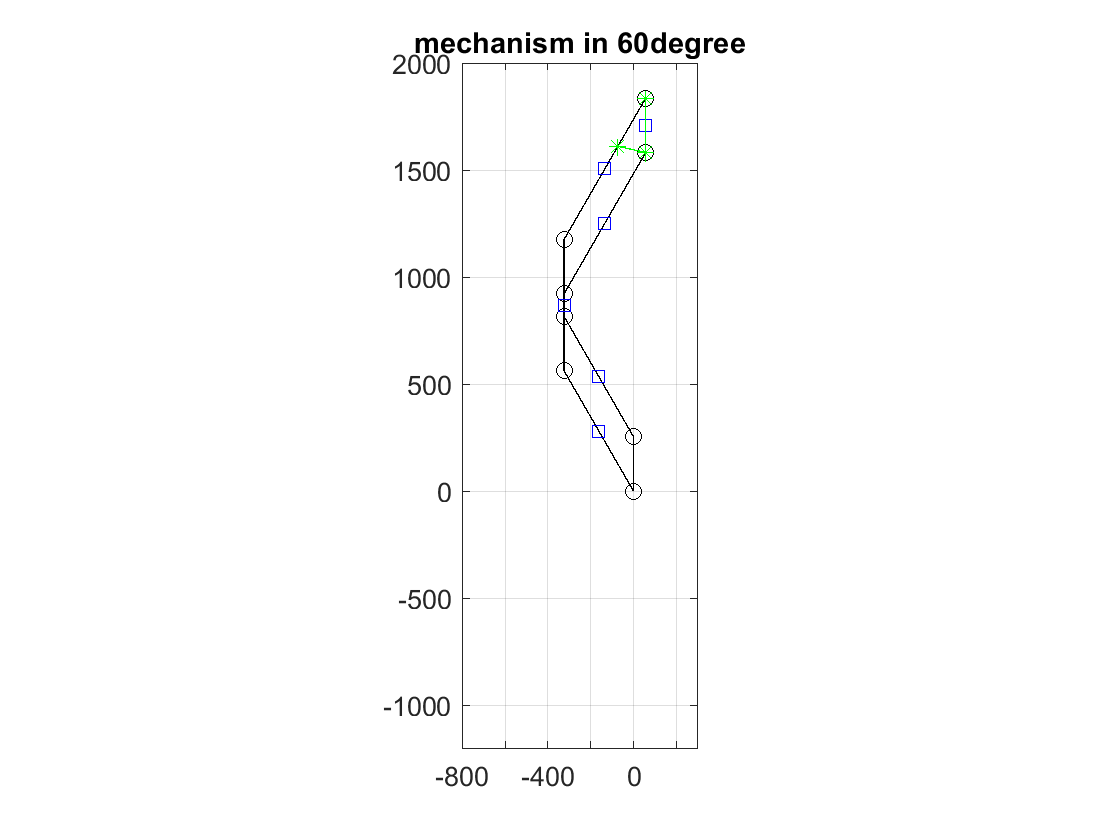

angled=60; %current theta angle
ind = find(abs(thetad-angled)<0.001); %find the index of the desired theta(check "find" documentation)

%支點演示
plot([O_4.x(ind) O_3.x(ind)], [O_4.y(ind) O_3.y(ind)], 'o-k'); hold on;
plot([O_4.x(ind) O4.x(ind)], [O_4.y(ind) O4.y(ind)], 'o-k'); hold on;
plot([O_3.x(ind) O3.x(ind)], [O_3.y(ind) O3.y(ind)], 'o-k'); hold on;
plot([O4.x(ind) O3.x(ind)], [O4.y(ind) O3.y(ind)], 'o-k'); hold on;
plot([O3.x(ind) O1.x(ind)], [O3.y(ind) O1.y(ind)], 'o-k'); hold on;
plot([O1.x(ind) O2.x(ind)], [O1.y(ind) O2.y(ind)], 'o-k'); hold on;
plot([O1.x(ind) O_1.x(ind)], [O1.y(ind) O_1.y(ind)], 'o-k'); hold on;
plot([O2.x(ind) O_2.x(ind)], [O2.y(ind) O_2.y(ind)], 'o-k'); hold on;
plot([O_1.x(ind) O_2.x(ind)], [O_1.y(ind) O_2.y(ind)], 'o-k'); hold on;

%質點演示
plot(mO1O_1.x(ind), mO1O_1.y(ind), 'sb'); hold on;
plot(mO2O_2.x(ind), mO2O_2.y(ind), 'sb'); hold on;
plot(mO3O_3.x(ind), mO3O_3.y(ind), 'sb'); hold on;
plot(mO4O_4.x(ind), mO4O_4.y(ind), 'sb'); hold on;
plot(mO_1O_2.x(ind), mO_1O_2.y(ind), 'sb'); hold on;
plot(mO2O4.x(ind), mO2O4.y(ind), 'sb'); hold on;

%彈性材料安裝點演示
% plot([P3.x(ind) P4.x(ind)], [P3.y(ind) P4.y(ind)], '*-g'); hold on;
% plot([P1.x(ind) P2.x(ind)], [P1.y(ind) P2.y(ind)], '*-g'); hold on;
for i = 1:length(P1i)
    plot([P1i(i).x(ind) P2i(i).x(ind)], [P1i(i).y(ind) P2i(i).y(ind)], '*-g'); hold on;
end
for j = 1:length(P3j)
    plot([P3j(j).x(ind) P4j(j).x(ind)], [P3j(j).y(ind) P4j(j).y(ind)], '*-g'); hold on;
end

hold off;
title("mechanism in "+angled + "degree");
axis([-800 300 -1200 2000]); %set plot size
grid on;
daspect([1 1 1]);

畫出各力矩

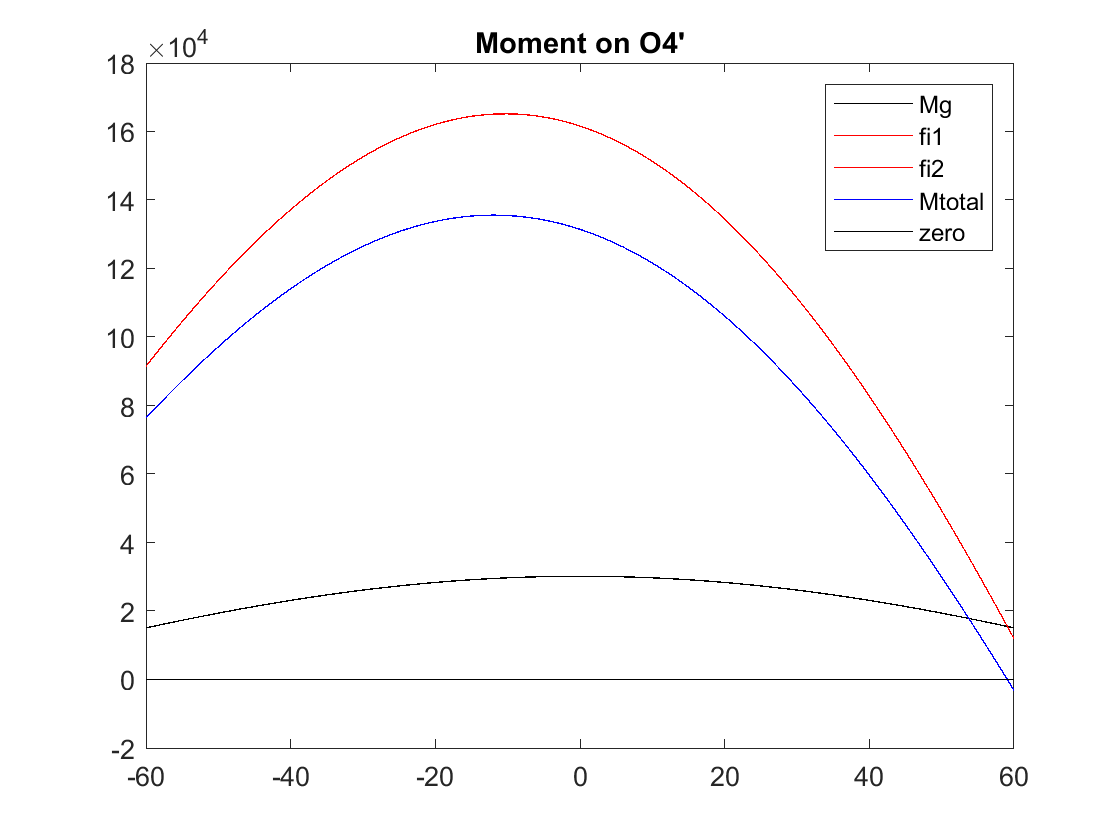

plot(thetad, Mg, 'k-', 'DisplayName','Mg'); hold on; %重力矩 黑色
for i = 1:length(Di) %各拉力矩 紅色
    plot(thetad, Mi(i,:), 'r-','DisplayName',"fi"+i);hold on;
end 

for j = 1:length(Dj) %各拉力矩 紅色
    plot(thetad, Mj(j,:), 'r-','DisplayName',"fj"+j);hold on;
end 

plot(thetad, Mtotal, 'b-','DisplayName',"Mtotal"); hold on;%藍色為總力矩
plot(thetad, zeros(1,length(thetar)), 'k',"DisplayName",'zero'); hold on
legend;  %顯示曲線名稱  

title('Moment on O4''')
% axis([-90 90 (-15*10^4) (15*10^4)]);
% legend('Mg','Mf1','Mf2','Mf3','Mtotal');
 hold off;

%find the root-mean-square error between Mtotal and 0 between two given
%angles
u= RMSE(Mtotal(find_ind(thetad, -75):find_ind(thetad, -30)), zeros(1, length(Mtotal(find_ind(thetad, -75):find_ind(thetad, -30)))))

rmse = NaN

u = NaN

function ind = find_ind(thetad, theta)
    ind = find(abs(thetad-theta)<0.001);
end
function rmse = RMSE(V1,V2)
    rmse = sqrt(mean((V1-V2).^2))
end